# Data Analyze

现象：

well train 阶段neuron和event之间的互信息更大，但之前阶段neuron之间的互信息更大，而且组合较为固定

close all;clear;clc;

## Analyze rat_010_07_04(well trained)

[M1, mPFC, ratios, eventTrain] = spikeTime2Train("data/rat_010_07_04.mat");
fprintf(['M1withSpike=%0.4f\nmPFCwithSpike=%0.4f\nM1multiSpike=%0.4f\n' ...
    'mPFCmultiSpike=%0.4f'], ratios)

M1withSpike=0.1314
mPFCwithSpike=0.0976
M1multiSpike=0.0499
mPFCmultiSpike=0.0402

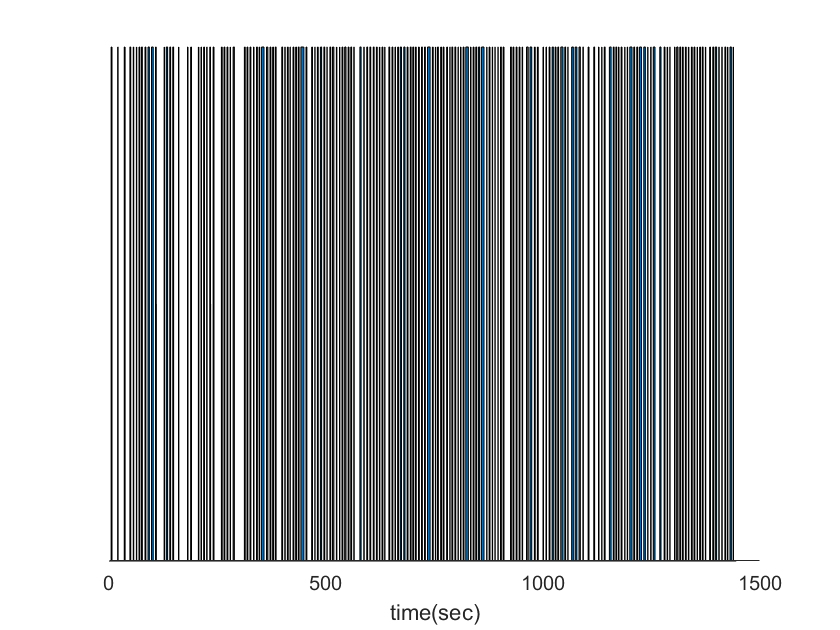

spikeLength = length(eventTrain);
figure
area(0.01:0.01:spikeLength*0.01, eventTrain)
set(gca, 'TickLength', [0 0])
set(gca, 'ytick', [])
set(gca, 'box', 'off')
set(gca, 'YColor', 'white')
xlabel("time(sec)")

event during 300.01s~910s seems continuously repeated. take for futher work.

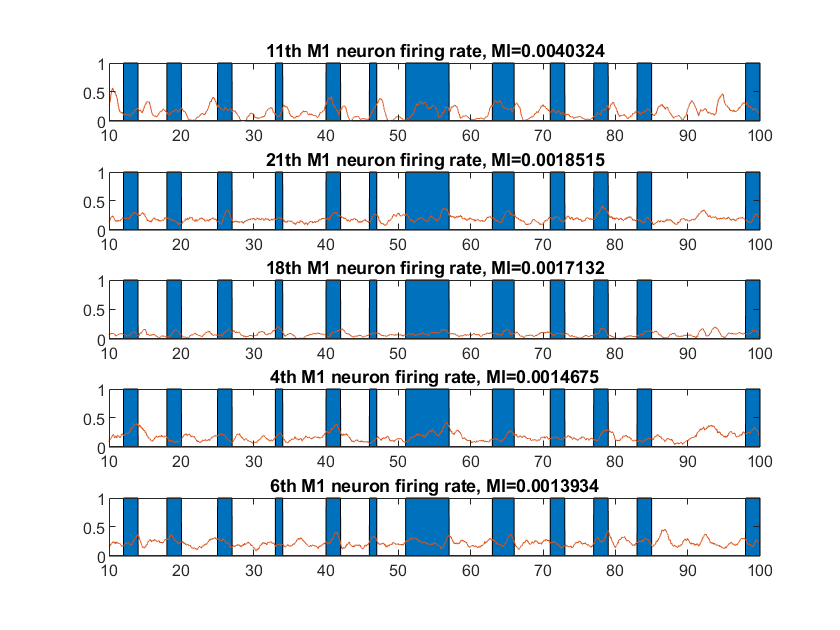

takenBins = 30001:91000;
eventTrain = eventTrain(takenBins)';
mPFC = mPFC(takenBins,:);
M1 = M1(takenBins,:);

emMI = mutualInformation(eventTrain, M1);
epMI = mutualInformation(eventTrain, mPFC);
nMI  = mutualInformation(M1, mPFC);

[mi, eM1index] = sort(emMI, 'descend');
t=10:0.01:100;
bins = 1000:10000;
figure
% subplot(6,1,1)
% area(t, eventTrain(bins))
% set(gca, 'TickLength', [0 0])
% set(gca, 'ytick', [])
% set(gca, 'box', 'off')
% set(gca, 'YColor', 'white')
% xlabel("time(sec)")
for i=1:5
  subplot(5,1,i)
  area(t, eventTrain(bins))
  hold on
  plot(t, gaussianSmooth(M1(bins, eM1index(i)), 50))
  hold off
  title([num2str(eM1index(i)), 'th M1 neuron firing rate, MI=', num2str(mi(i))])
end

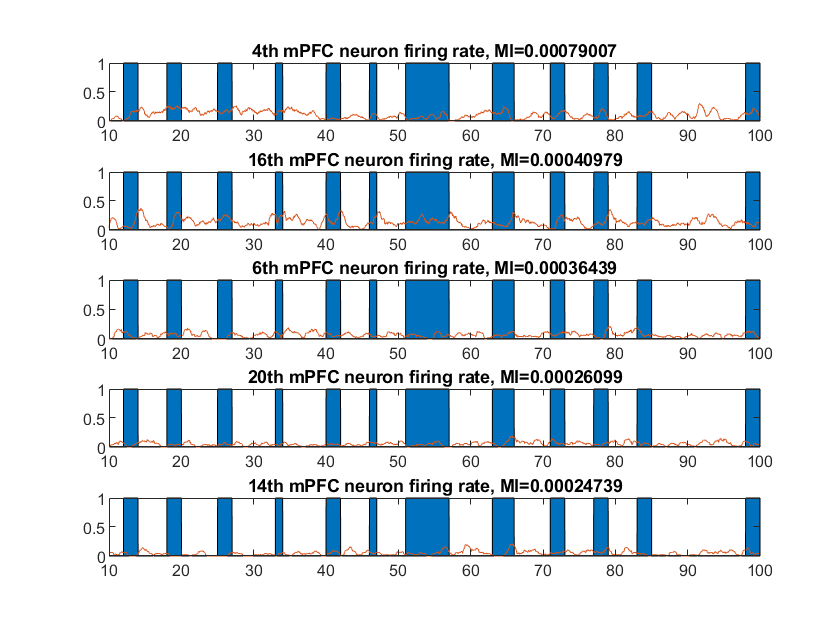

[mi, emPFCindex] = sort(epMI, 'descend');
figure
% subplot(6,1,1)
% area(t, eventTrain(bins))
% set(gca, 'TickLength', [0 0])
% set(gca, 'ytick', [])
% set(gca, 'box', 'off')
% set(gca, 'YColor', 'white')
% xlabel("time(sec)")
for i=1:5
  subplot(5,1,i)
  area(t, eventTrain(bins))
  hold on
  plot(t, gaussianSmooth(mPFC(bins, emPFCindex(i))*2, 50))
  hold off
  title([num2str(emPFCindex(i)), 'th mPFC neuron firing rate, MI=', num2str(mi(i))])
end

与event互信息前五的neuron之间的互信息

nMI(eM1index(1:5), emPFCindex(1:5))

ans = 	1.0e+-3 *

    0.0026    0.1747    0.0642    0.1050    0.0460
    0.1640    0.0757    0.1176    0.0253    0.1063
    0.2213    0.0035    0.0026    0.0539    0.0041
    0.0274    0.0954    0.1087    0.0217    0.1824
    0.0187    0.0008    0.0203    0.0032    0.0201


event-M1前五对应的五个mPFC

[mi, mPFCindex] = sort(nMI(eM1index(1:5),:), 2, 'descend');
disp(num2str(mPFCindex(:, 1:5)))

16  10  20   1   6
17  10  12   4   6
 4  12   3   2  11
17  12  14   6  11
 1  11  22  13   2


以及他们的互信息

mi(:, 1:5)

ans = 	1.0e+-3 *

    0.1747    0.1393    0.1050    0.0749    0.0642
    0.2855    0.2307    0.1643    0.1640    0.1176
    0.2213    0.1228    0.0997    0.0721    0.0579
    0.3708    0.2288    0.1824    0.1087    0.1020
    0.0724    0.0659    0.0505    0.0450    0.0393


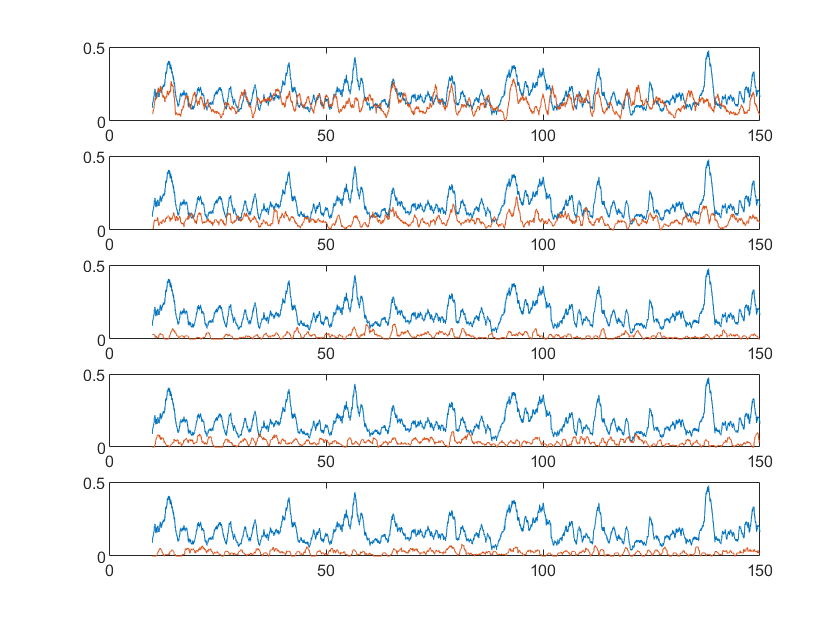

t=10:0.01:150;
bins = 1000:15000;
figure
for i=1:5
  subplot(5,1,i)
  plot(t, gaussianSmooth(M1(bins, eM1index(4)), 50))
  hold on
  plot(t, gaussianSmooth(mPFC(bins, mPFCindex(4,i)), 50))
  hold off
end

M1spike = M1(:, eM1index(4));
mPFCspike = mPFC(:, mPFCindex(4,:));
save("data/rat_010_07_04_selected.mat", "M1spike", "mPFCspike", "eventTrain")

## Analyze rat010_0615(critical day)

[M1, mPFC, ratios, eventTrain] = spikeTime2Train("data/data_rat010_0615_event");
fprintf(['M1withSpike=%0.4f\nmPFCwithSpike=%0.4f\nM1multiSpike=%0.4f\n' ...
    'mPFCmultiSpike=%0.4f'], ratios)
spikeLength = length(eventTrain);
figure
area(0.01:0.01:spikeLength*0.01, eventTrain)
set(gca, 'TickLength', [0 0])
set(gca, 'ytick', [])
set(gca, 'box', 'off')
set(gca, 'YColor', 'white')
xlabel("time(sec)")

event during 820.01s~1600s seems continuously repeated. take for futher work.

takenBins = 82001:160000;
spikeLength = length(takenBins);
eventTrain = eventTrain(takenBins)';
mPFC = mPFC(takenBins,:);
M1 = M1(takenBins,:);

emMI = mutualInformation(eventTrain, M1);
epMI = mutualInformation(eventTrain, mPFC);
nMI  = mutualInformation(M1, mPFC);

[mi, eM1index] = sort(emMI, 'descend');
t=10:0.01:300;
bins = 1000:30000;
figure
% subplot(6,1,1)
% area(t, eventTrain(bins))
% set(gca, 'TickLength', [0 0])
% set(gca, 'ytick', [])
% set(gca, 'box', 'off')
% set(gca, 'YColor', 'white')
% xlabel("time(sec)")
for i=1:5
  subplot(5,1,i)
  area(t, eventTrain(bins))
  hold on
  plot(t, gaussianSmooth(M1(bins, eM1index(i)), 50))
  hold off
  title([num2str(eM1index(i)), 'th M1 neuron firing rate, MI=', num2str(mi(i))])
end
[mi, emPFCindex] = sort(epMI, 'descend');
figure
% subplot(6,1,1)
% area(t, eventTrain(bins))
% set(gca, 'TickLength', [0 0])
% set(gca, 'ytick', [])
% set(gca, 'box', 'off')
% set(gca, 'YColor', 'white')
% xlabel("time(sec)")
for i=1:5
  subplot(5,1,i)
  area(t, eventTrain(bins))
  hold on
  plot(t, gaussianSmooth(mPFC(bins, emPFCindex(i))*2, 50))
  hold off
  title([num2str(emPFCindex(i)), 'th mPFC neuron firing rate, MI=', num2str(mi(i))])
end

与event互信息前五的neuron之间的互信息

nMI(eM1index(1:5), emPFCindex(1:5))

event-M1前五对应的五个mPFC

[mi, mPFCindex] = sort(nMI(eM1index(1:5),:), 2, 'descend');
disp(num2str(mPFCindex(:, 1:8)))

以及他们的互信息

mi(:, 1:8)
t=10:0.01:150;
bins = 1000:15000;
figure
for i=1:5
  subplot(5,1,i)
  plot(t, gaussianSmooth(M1(bins, 7), 50))
  hold on
  plot(t, gaussianSmooth(mPFC(bins, mPFCindex(1,i)), 50))
  hold off
end
t=10:0.01:150;
bins = 1000:15000;
figure
for i=1:5
  subplot(5,1,i)
  plot(t, gaussianSmooth(M1(bins, 11), 50))
  hold on
  plot(t, gaussianSmooth(mPFC(bins, mPFCindex(1,i)), 50))
  hold off
end
t=10:0.01:150;
bins = 1000:15000;
figure
for i=1:5
  subplot(5,1,i)
  plot(t, gaussianSmooth(M1(bins, 17), 50))
  hold on
  plot(t, gaussianSmooth(mPFC(bins, mPFCindex(1,i)), 50))
  hold off
end

可以看出在critical day的mPFC与M1的联系似乎更为紧密，因此选取其中部分数据来跑模型

依然选取其中mutual information比较大的来做数据集，mPFC的数量是自己估计的

M1neurons   = [7 11 17];
mPFCneurons = [5 6 7 8 13];
M1spike = M1(:, M1neurons);
mPFCspike = mPFC(:, mPFCneurons);
save("data/data_rat010_0615_spike_train_selected.mat", "M1spike", "mPFCspike", "eventTrain")